# Compare

clear
design_params;
if true
    jaksa;
    jaksa_lv;
    jaksa_lv_oo;
    jaksa_lv_drom;
end

pl_A_hole = 0.7854

pl_A_hole = 0.7854

pl_A_hole = 0.7854

pl_rom = 9.0000e-04

v_stopper = 115.4535

jaksa_open_close = importdata("jaksa_open_close.mat");
jaksa_lv_open_close = importdata("jaksa_lv_open_close.mat");
jaksa_lv_oo_open_close = importdata("jaksa_lv_oo_open_close.mat");
jaksa_lv_drom_open_close = importdata("jaksa_lv_drom_open_close.mat");

## Displacement

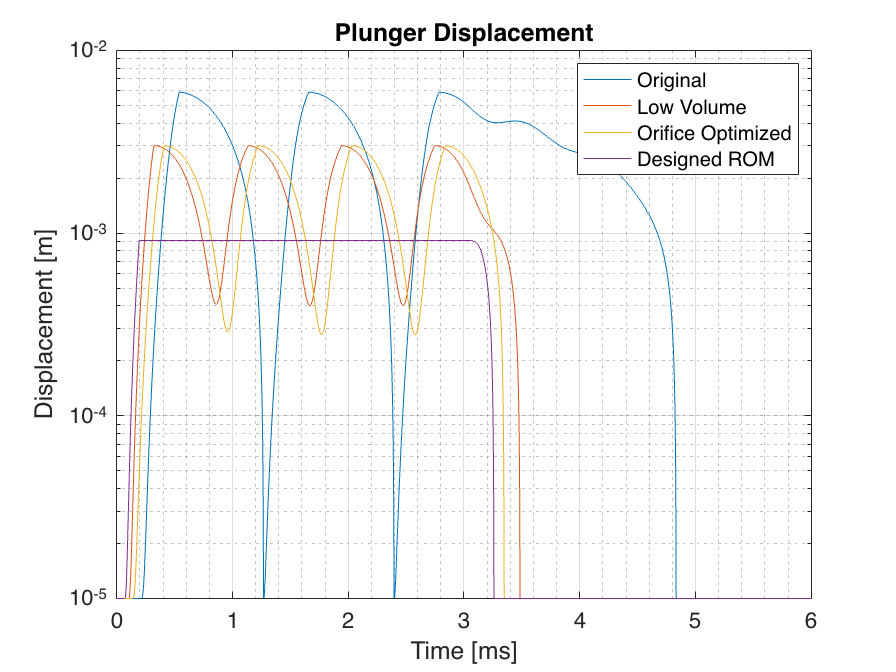

figure('DefaultAxesFontSize',14)
semilogy(...
    jaksa_open_close.t*10^3,jaksa_open_close.x+10^-5,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.x+10^-5,...
    jaksa_lv_oo_open_close.t*10^3,jaksa_lv_oo_open_close.x+10^-5,...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.x+10^-5 ...
    )
axis([0 6 10^-5 10^-2])
legend('Original','Low Volume','Orifice Optimized','Designed ROM')
grid on, grid minor, xlabel('Time [ms]'), ylabel('Displacement [m]'), title('Plunger Displacement')

## Volume

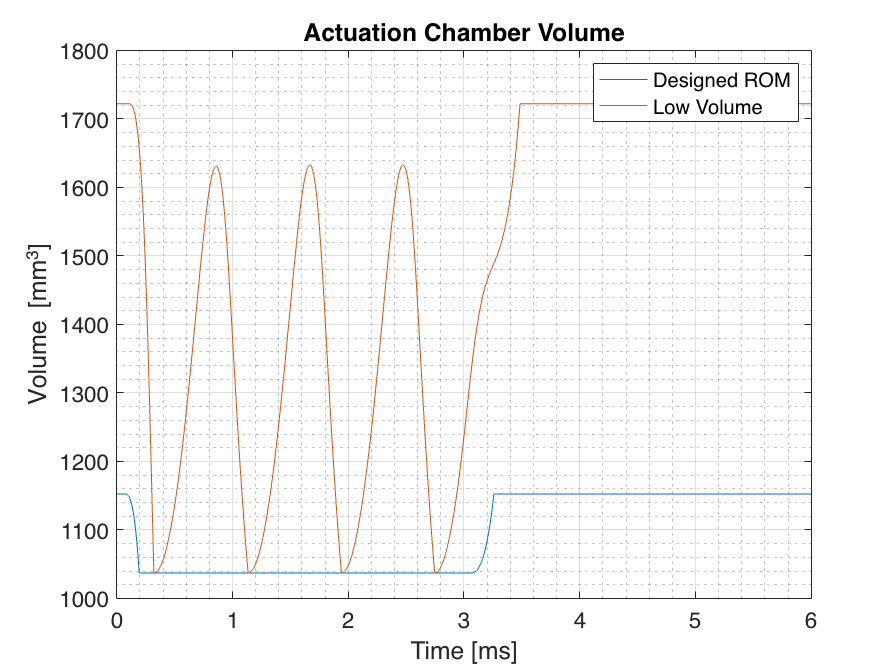

figure('DefaultAxesFontSize',14)
plot(jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.V_ac,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.V_ac)
legend('Designed ROM','Low Volume')
grid on, grid minor, xlabel('Time [ms]'), ylabel('Volume [mm^3]'), title('Actuation Chamber Volume')

## Pressures

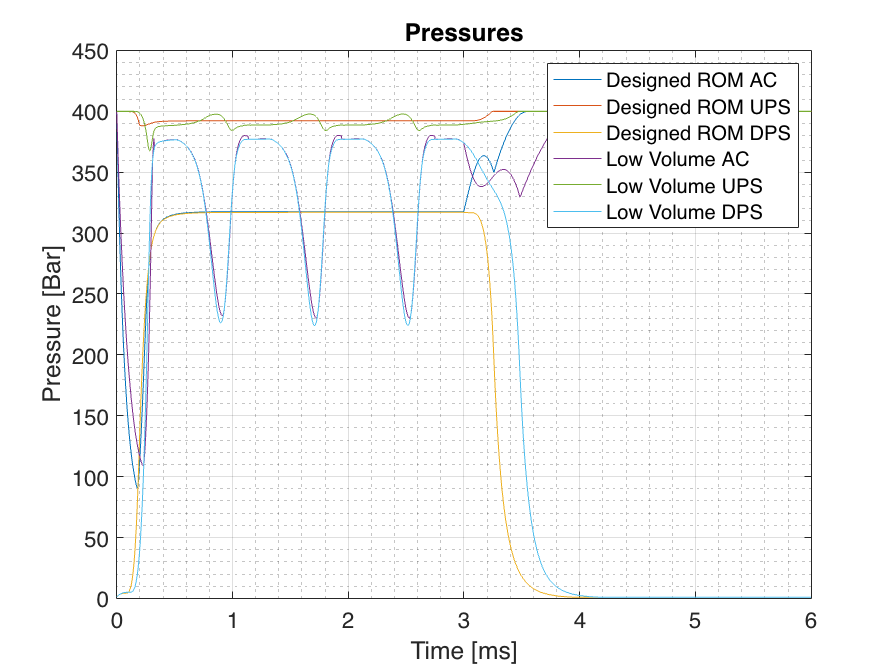

figure('DefaultAxesFontSize',14)
% plot(...
%     jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.P_u,...
%     jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.P_ac,...
%     jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.P_d,...
%     jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.P_dps,...
%     jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.P_ups,...
%     jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_u,...
%     jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_ac,...
%     jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_d,...
%     jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_dps,...
%     jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_ups...
%     )
%legend('U','AC','D','DPS','UPS','U','AC','D','DPS','UPS')
plot(...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.P_ac,...
     jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.P_ups,...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.P_dps,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_ac,...
     jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_ups,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_dps...
    )
grid on, grid minor, xlabel('Time [ms]'), ylabel('Pressure [Bar]'), title('Pressures')
legend('Designed ROM AC','Designed ROM UPS','Designed ROM DPS',...
    'Low Volume AC','Low Volume UPS','Low Volume DPS')

## Forces

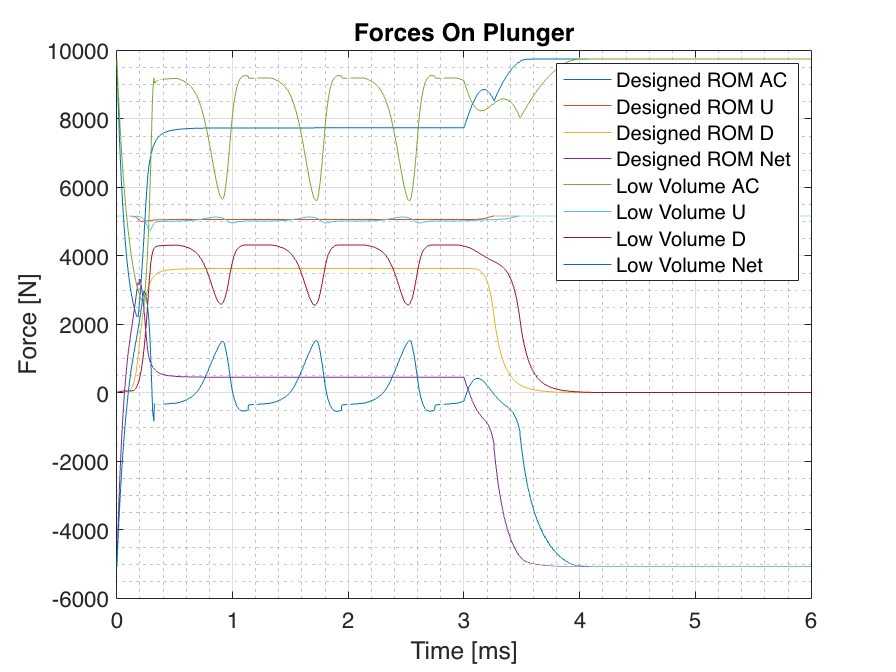

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.F_ac,...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.F_u,...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.F_d,...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.F,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F_ac,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F_u,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F_d,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F...
    )
grid on, grid minor, xlabel('Time [ms]'), ylabel('Force [N]'), title('Forces On Plunger')
legend(...
    'Designed ROM AC','Designed ROM U','Designed ROM D','Designed ROM Net',...
    'Low Volume AC','Low Volume U','Low Volume D','Low Volume Net'...
    )

## Net force

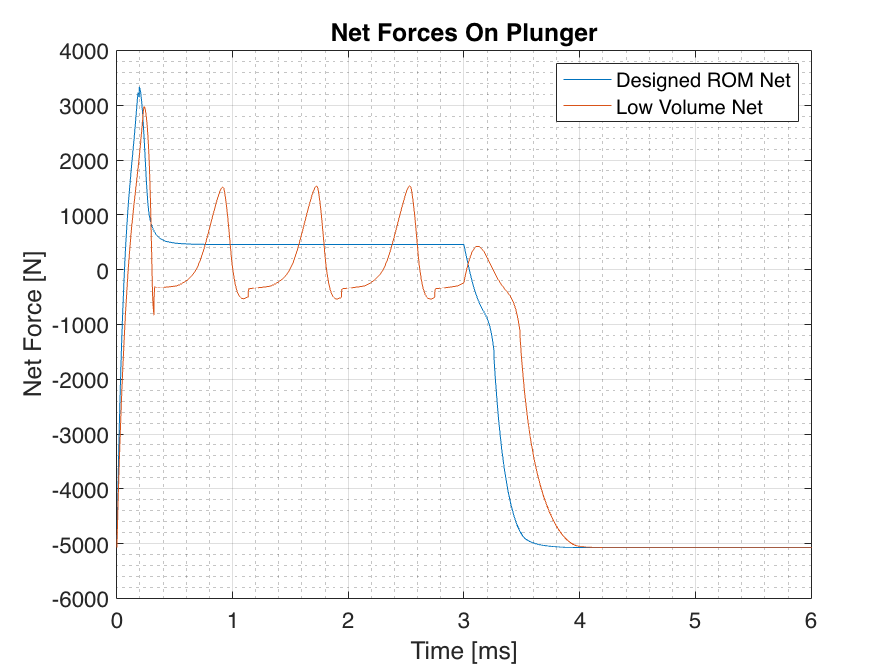

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.F,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F...
    )
grid on, grid minor, xlabel('Time [ms]'), ylabel('Net Force [N]'), title('Net Forces On Plunger')
legend(...
    'Designed ROM Net',...
    'Low Volume Net'...
    )

## UPD to DPS

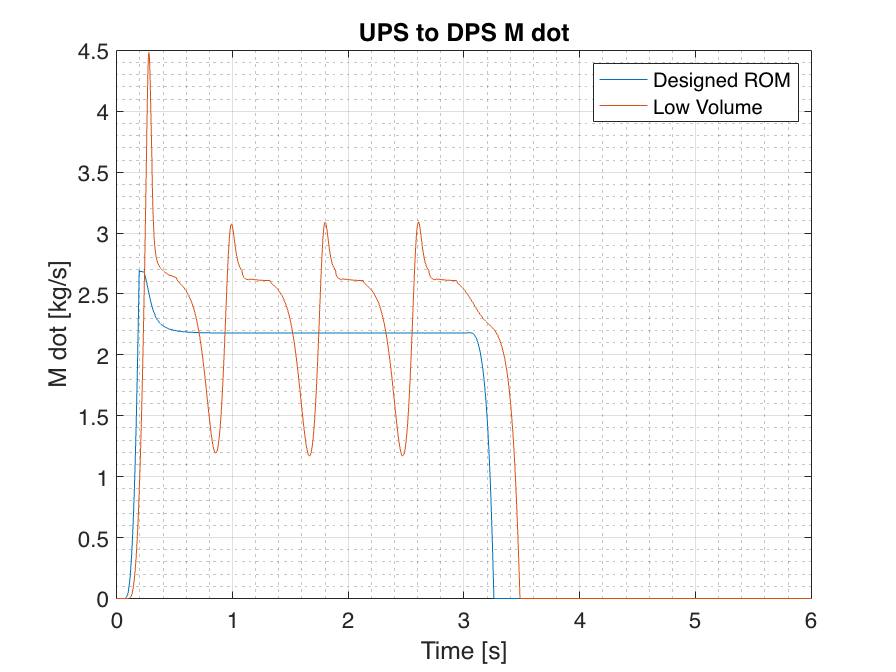

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.m_dot_ups_dps,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.m_dot_ups_dps...
    )
grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('UPS to DPS M dot')
legend('Designed ROM', 'Low Volume')

## AC net m dot

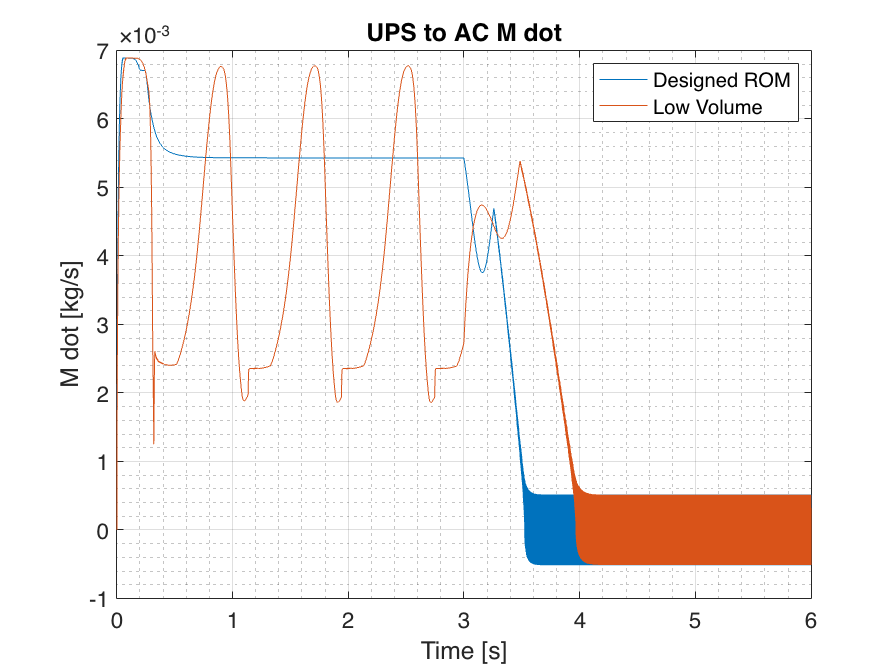

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.m_dot_ups_ac,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.m_dot_ups_ac...
    )
grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('UPS to AC M dot')
legend('Designed ROM', 'Low Volume')

## M dot DPS to D

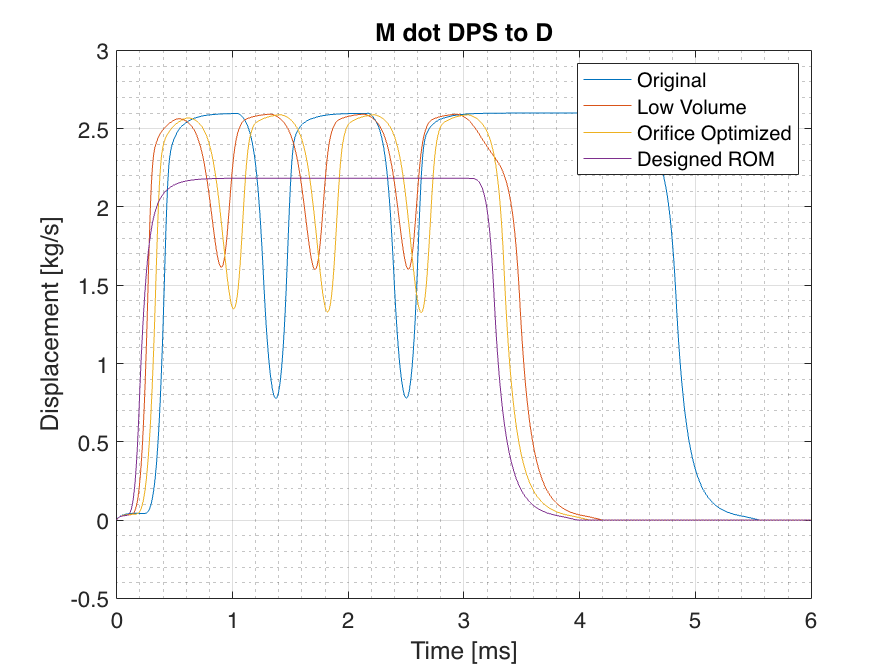

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_open_close.t*10^3,jaksa_open_close.m_dot_dps_d,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.m_dot_dps_d,...
    jaksa_lv_oo_open_close.t*10^3,jaksa_lv_oo_open_close.m_dot_dps_d,...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.m_dot_dps_d...
    )
legend('Original','Low Volume','Orifice Optimized','Designed ROM')
grid on, grid minor, xlabel('Time [ms]'), ylabel('Displacement [kg/s]'), title('M dot DPS to D')